# Laboratorio didattico di misure meccaniche e termiche

L'attività didattica ha lo scopo di utilizzare il comune smartphone per svolgere delle acquisizioni relative al segnale di accelerazione durante lo svolgimento di specifiche azioni.

Durante l'esercitazione verrà utilizzato un database necessario per mettere in pratica algoritmi di classificazione.

Nello specifico, il database contiene dei dati di accelerazione lungo le 3 componenti x,y e z relativi a 30 soggetti mentre svolgono 6 attività: 

- Cammino

- Salita scale

- Discesa scale

- Sedersi

- Fermo in piedi

- Fermo sdraiato

Sarà necessario analizzare i dati nel dominio del tempo e della frequenza per evidenziare le caratteristiche del segnale. Tali features dovranno successivamente essere utilizzare per addestrare un classificatore in grado di distinguere le diverse azioni.

## Caricamento dei dati

Il file "*RecordedAccelerationsBySubject.mat"* contiene i valori di accelerazione lungo le componenti x,y e z ottenute dall’accelerometro dello smartphone mentre il soggetto svolge specifiche attività. 

Comunemente gli assi relativi al sensore di accelerazione all'interno dello smartphone sono orientati come in figura:

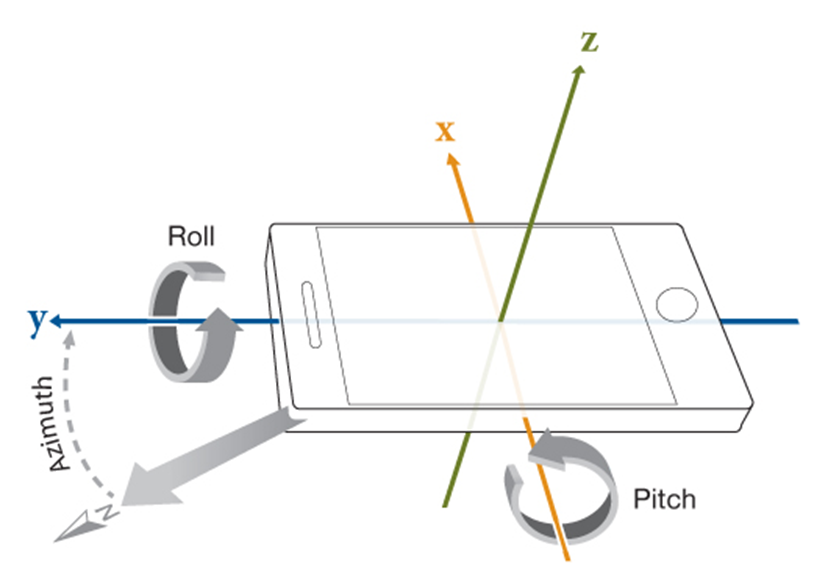

X = direzione verticale

Z = direzione saggittale (avanti/dietro)

Ad ogni attività è stato assegnato un codice univoco:

**            1  = Cammino**

**            2 = Salita scale**

**            3 = Disce sascale**

**            4 = Sedersi**

**            5 = Fermo in piedi**

**            6 = Fermo sdraiato**

All’interno del file si trova la struttura "*subjects"* che contiene le acquisizioni relative a 30 soggetti:

• subjects(30x1) è un vettore di strutture che contiene i seguenti campi (ogni elemento si riferisce ad un singolo soggetto):

  • actid: contiene un vettore colonna relativo ai codici specifici dell’attività

  • totalacc(:x3): è una matrice composta da 3 colonne relative alle 3 componenti dell'accelerazione: 

- colonna 1 = accelerazione lungo x

- colonna 2 = accelerazione lungo y

- colonna 3 = accelerazione lungo z

•  *fs* è la frequenza di campionamento

clear 
close
clc

load RecordedAccelerationsBySubject.mat
subjects    

subjects = 1×30 struct array with fields:
    actid
    totalacc


### *Task n°1 :*

Realizzare una funzione responsabile del caricamento del vettore dell’accelerazione lungo la componente **x** per il soggetto **n **(con 1≤ n ≥30). Nell'esempio viene riportata una funzione dal nome "Get_acceleration".

INPUT: 

- Id del soggetto [da 1 a 30]

- Componente accelerazione [1 per x, 2 per y, 3 per z]

- dati [subjects]

- fs [freq campionamento]

OUTPUT:

- Accelerazione

- Label azioni corrispondenti al vettore di accelerazione

- Asse dei tempi

Di seguito un **esempio** che spiega come accedere ai dati del vettore di strutture e ne plotta i dati estratti:

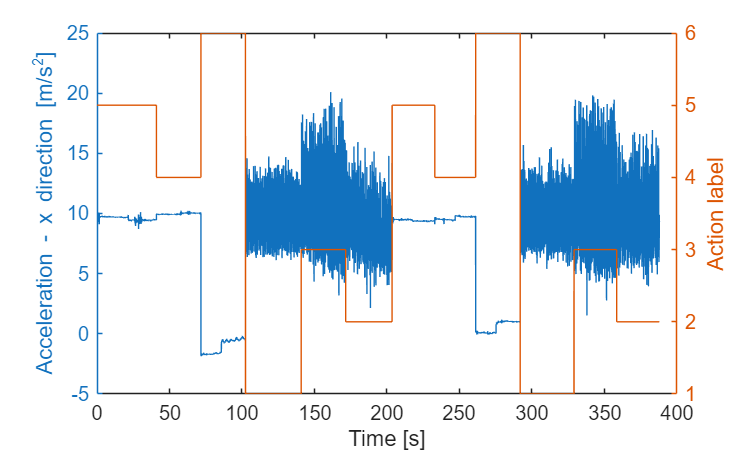

figure, yyaxis left, plot((1:length(subjects(2).totalacc(:,1)))/fs,(subjects(2).totalacc(:,1))) % colonna 1 -> direzione X
ylabel ('Acceleration - x direction [m/s^2]')
hold on
yyaxis right, plot((1:length(subjects(2).totalacc(:,1)))/fs,subjects(2).actid)
ylabel ('Action label')
yticks([1, 2, 3, 4, 5, 6])
xlabel ('Time [s]')
hold off

% Componenti accelerometro x,y,z
subject = 1; % scelgo il soggetto (da 1 a 30)
direction = 'x'; % sceglo la direzione verticale
[acceleration, acc_id, time] = Get_acceleration(subject, direction, subjects, fs);

Definisco la variabile fs ed il vettore corrsipondente alle 6 azioni

% ID attività. 
% 1 = Walking; 
% 2 = Walking up stairs; 
% 3 = Walking down stairs; 
% 4= Sitting;
% 5 = Standing; 
% 6= Laying
activities = {'Walking'  'WalkingUpstairs'  'WalkingDownstairs'  'Sitting' 'Standing'  'Laying'};

## Visualizzazione dei dati grezzi

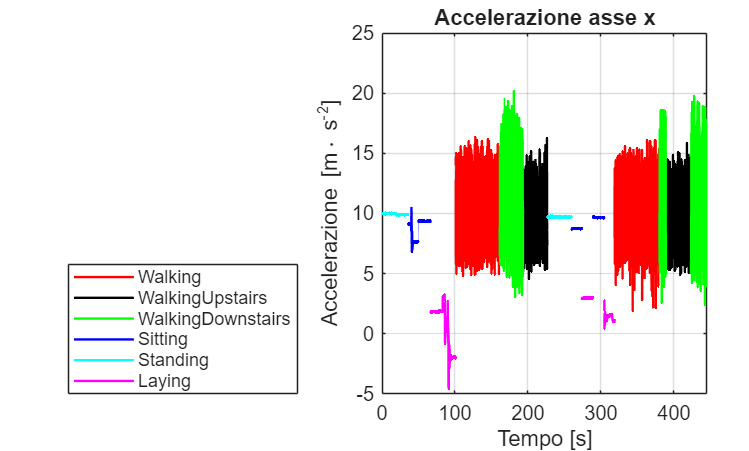

Visualizzazione_accelerazioni(acceleration,acc_id,time,direction)

## Istogrammi

Evidenzio graficamente le differenze andando ad analizzare la media delle misure.

Sfrutto il live script per vedere come cambiano gli istogrammi in base alle azioni considerate

Utilizzo due slide numerici relativi alle azioni da confrontare

#### Esempio 1: Cammino vs sdraiato

Realizzare l’istogramma relativo ai dati di accelerazione per attività cammino (id = 1) e sdraiato (id = 6)

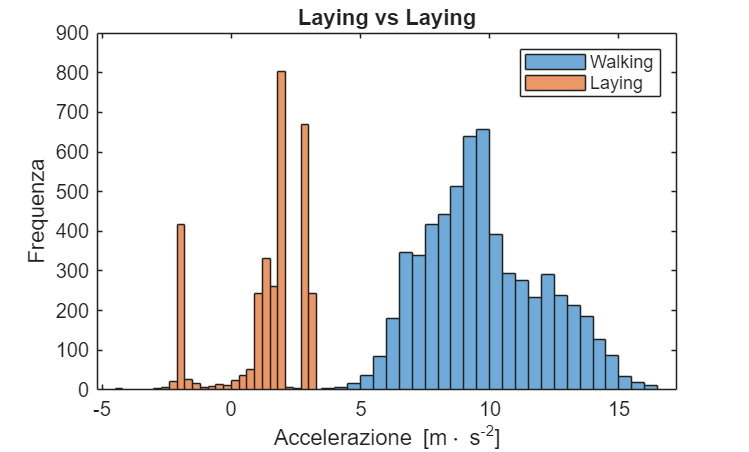

% ID attività. 
% 1 = Walking; 
% 2 = Walking up stairs; 
% 3 = Walking down stairs; 
% 4= Sitting;
% 5 = Standing; 
% 6= Laying

activity_one = 1;
activity_two = 6;

acceleration_h1 = acceleration(acc_id == activity_one);
acceleration_h2 = acceleration(acc_id == activity_two);

% Seleziono solamente i dati di interesse
figure
histogram(acceleration_h1)
hold on
histogram(acceleration_h2)
legend ([cellstr(activities(activity_one)) cellstr(activities(activity_two))]);
xlabel('Accelerazione [m\cdot s^{-2}]')
ylabel('Frequenza')
title (strcat(activities(activity_two), " vs ", activities(activity_two)))

E' sufficiente un'analisi di questo tipo per determinare con esattezza l'azione che sto svolgendo ?

#### *Task n°2 :* Confrontate a due a due azioni diverse cercando di immaginare quanto sia possibile discriminarle a partire dal solo istogramma

Nota: Cammino vs salita scale ad esempio i due istogrammi si confondono l'uno con l'altro, ovvero le due variabili sono 'compatibili'.

Visualizzare i vari istogrammi cambiando l'id. Cosa cambia nell'istogramma ? Possiamo ancora distinguere chiaramente le due azioni?

## Analisi nel dominio della frequenza

Visualizzare la trasformata (Spettro) delle accelerazioni corrispondenti alle diverse azioni.

#### *Task n°3 : Trasformata di Fourier*

Implementare una funzione chiamata "Plot_FFT" che ricava e plotta la FFT dell'accelerazione per le diverse azioni allo scopo poi di eliminare la componente continua in un passaggio successivo in cui verrà chiesto di applicare un fiiltro passa-alto che vada bene per tutte le azioni.

Attenzione, come asse delle frequenze è utile che voi lo normalizzate alla frequenza di Nyquist (perchè i filtri poi si progettano a partire dalle freqeunze normalizzate).

https://it.mathworks.com/help/matlab/math/fourier-transforms.html

INPUT: 

- Segnale

- Frequenza di campionamento

- Attività

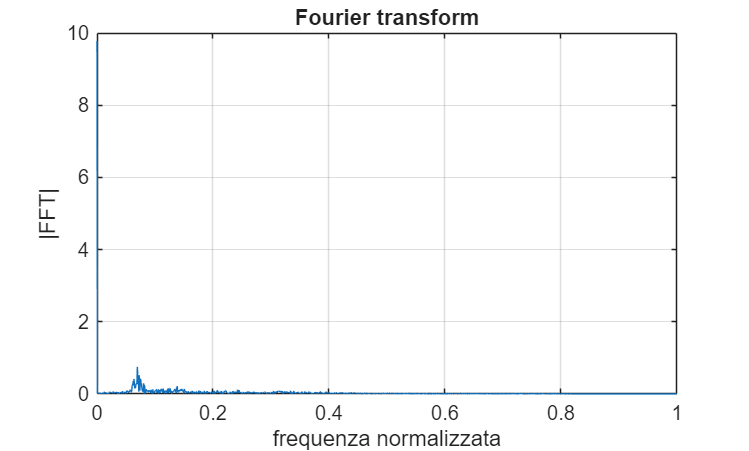

activity_fft = 3;

% Seleziono lo stato di interesse : cammino
time_w = time(acc_id == activity_fft);
acceleration_w = acceleration(acc_id == activity_fft);
figure
Plot_FFT(acceleration_w, fs);

#### *Task n°4 : Confrontare gli Spettri dei segnali a due a due per capire se dalla sola trasformata si riesce a discernere tra tutte le coppie di azioni, ovvero di discernere una rispetto a tutte le altre per effettuare l'action recognition così detto in Machine Learning*

Utilizzo la stessa funzione per visualizzare gli spettri di due azioni alla volta. 

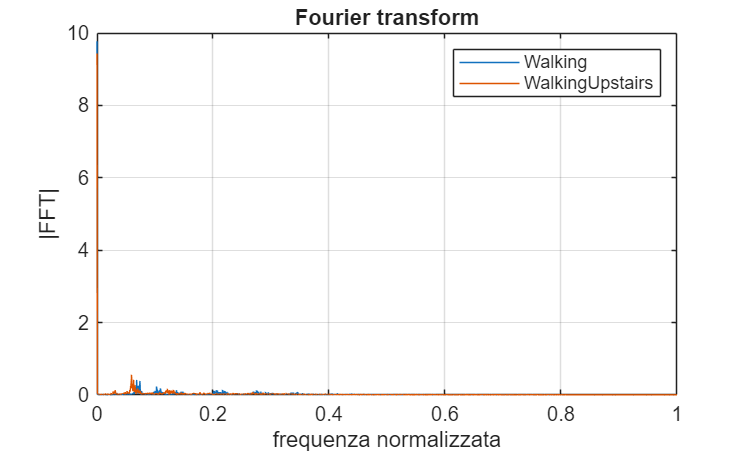

activity_one_fft = 1;
activity_two_fft = 2;

% Seleziono lo stato di interesse :
acceleration_w = acceleration(acc_id == activity_one_fft);
figure
Plot_FFT(acceleration_w, fs);
hold on

% Seleziono secondo stato di interesse :
time_s = time(acc_id==activity_two_fft);
acceleration_s = acceleration(acc_id==activity_two_fft);
Plot_FFT(acceleration_s, fs);
legend ([cellstr(activities(activity_one_fft)) cellstr(activities(activity_two_fft))]);

## Analisi nel dominio del tempo

#### *Task n°5 : Realizzazione di un filtro passa alto*

Realizzare una funzione "**Filtro**" che implementa un filtro passa alto da applicare ai segnali di accelerazione (dividendoli per attività), così da eliminare la componente continua del segnale e visualizzare le componenti dinamiche. 

Determinare la frequenza di taglio del filtro passa alto che vada bene per tutti i segnali di accelerazione in base all'attività specificata nel Task n°3

Provare con diversi ordini del filtro.

Usare i comandi butter e filter.

activity_ID = 1;
acceleration_w = acceleration(acc_id == activity_ID);

INPUT: 

- Segnale "acceleration_w"

- Frequenza di campionamento

OUTPUT: 

- B del comando butter

- A idem

PLOT

- segnale originario e segnale filtrato su stesso grafico

-  visualizzare le caratteristiche del filtro, utilizzando la funzione   "fvtool".

[B, A] = Filtro(acceleration_w, fs)

Not enough input arguments.

Error in Filtro (line 5)
[B, A] = butter(order, tau, 'high');
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

## Riorganizzazione dei campioni statistici

I dati sono stati riorganizzati in modo da avere ciascuna azione suddivisa in **n** set (campioni statistici) in riga ciascuna da **500** dati campionati. Ciascun set è un campione statistico.

Tanti set serviranno  per **allenare il classificatore**!

I dati sono salvati nel file "CampioniStatisticiPerAttività_500" e sono organizzati in una Cell Array di 6 elementi chiamato "stat_c":

**            Posizione 1  = Cammino**

**            Posizione 2 = Salita scale**

**            Posizione  3 = Disce sascale**

**            Posizione 4 = Sedersi**

**            Posizione 5 = Fermo in piedi**

**            Posizione 6 = Fermo sdraiato** 

Le tre componenti realizzano ciascuna una matrice nx500. Quindi ogni elemento del Cell Array è organizzato in forma di matrice 3D con dimensioni (*n x 500 x 3*) come in figura:

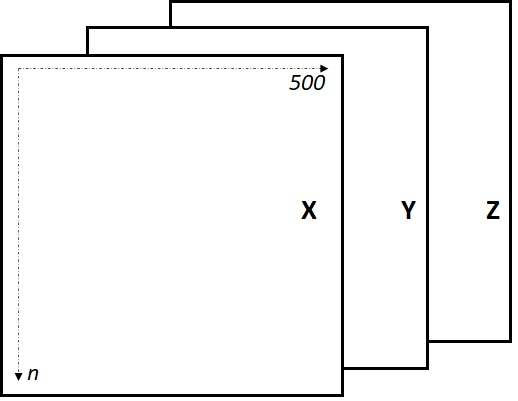

I dati relativi ai diversi soggetti a questo punto vengono messi tutti assieme. Quindi le registrazioni di ciascuno non sono più distinguibili. Ma questo non è un problema per il classificatore che dovrà  lavorare su tutti i soggetti indistintamente.

load CampioniStatisticiPerAttività_500.mat  

Di seguito un **esempio** su come estrarre i diversi campioni statistici per ciascuna azione:

activity_ID = 1;
component = 1;
sample_Number = 1;
sampleStat = stat_c{activity_ID}(sample_Number,:,component);
plot((1:length(sampleStat))/fs,sampleStat)
xlabel ('Time [s]')
ylabel ('Acceleration [m/s^2]')
title('Set campione statistico estratto dalla Cell Array')

## FUNZIONE PER RICAVARE LE FEATURES

#### *Task n°5 : Features*

Nello step di estrazione delle features viene generata una funzione responsabile del salvataggio delle caratteristiche fondamentali del segnale, che verranno successivamente utilizzate per la classificazione.

Nello specifico, si richiede di realizzare una funzione in grado di estrarre 4 features per ogni direzione, partendo dai dati buffer di accelerazione:

- Media del segnale lungo le 3 componenti

- Deviazione standard del segnale lungo le 3 componenti

- Valore del picco principale della FFT del segnale

- Posizione del picco principale della FFT del segnale

Scrivere la funzione per estrarre le features di interesse per ogni buffer.

INPUT: 

- Cell Array [stat_c]

- Frequenza di campionamento [fs]

- A, B del filtro passa alto prima ricavato (serve per calcolare la deviazione standard in modo più accurato)

OUTPUT:

- Matrice $m\;x\;13\;$(4 features per 3 direzioni, ID attività) contenente le **Features** e la **Label** (ultima colonna) richieste 

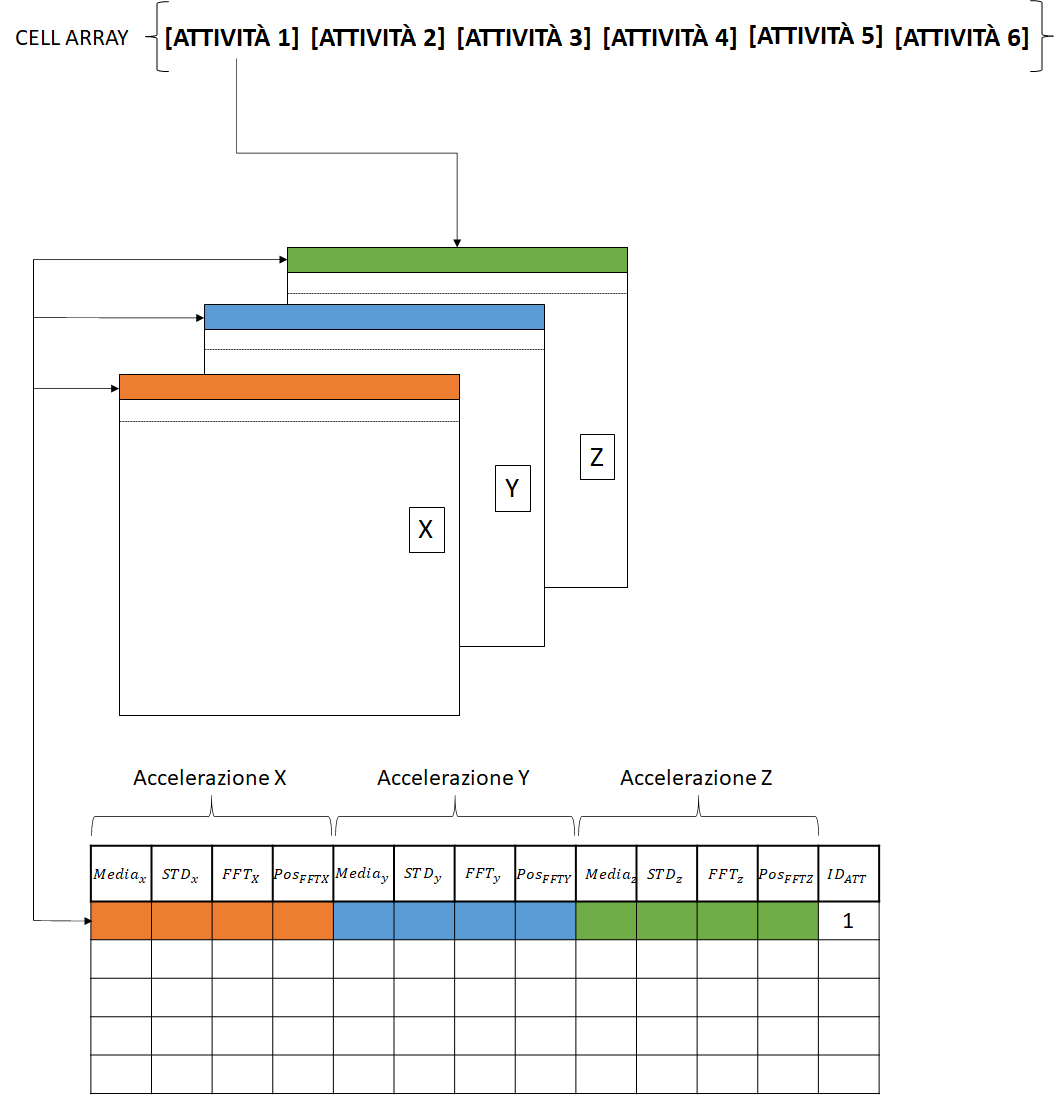

### **Estrazione delle features**

features = ExtractSignalFeatures(stat_c, fs, A, B);

featlabels = {'Media x', 'STD x', 'ampiezza picco FFT x', 'posizione picco FFT x', 'Media y', 'STD y', 'ampiezza picco FFT y', 'posizione picco FFT y', 'Media z', 'STD z', 'ampiezza picco FFT z', 'posizione picco FFT z', 'Activity ID'};

## ALGORITMO DI CLASSIFICAZIONE

In questa fase viene realizzato il classificare, partendo dalle features precedentemente estratte.

E' necessario realizzare una tabella per importare i dati nell'algoritmo di classificazione.

featT = array2table(features, 'VariableNames',featlabels); % tabella della features

#### *Task n°6 : Classificazione*

*Realizzare il classificatore utilizzando* il tool di MatLab "*classificationLearner*" (https://it.mathworks.com/help/stats/classificationlearner-app.html).

Step necessari per la realizzazione classificatore:

- Importare i dati: Nuova sessione -> Data set variable -> tabella delle features 

            NB: la colonna della risposta, sarà quella precedentemente salvata nella colonna Acitivity ID

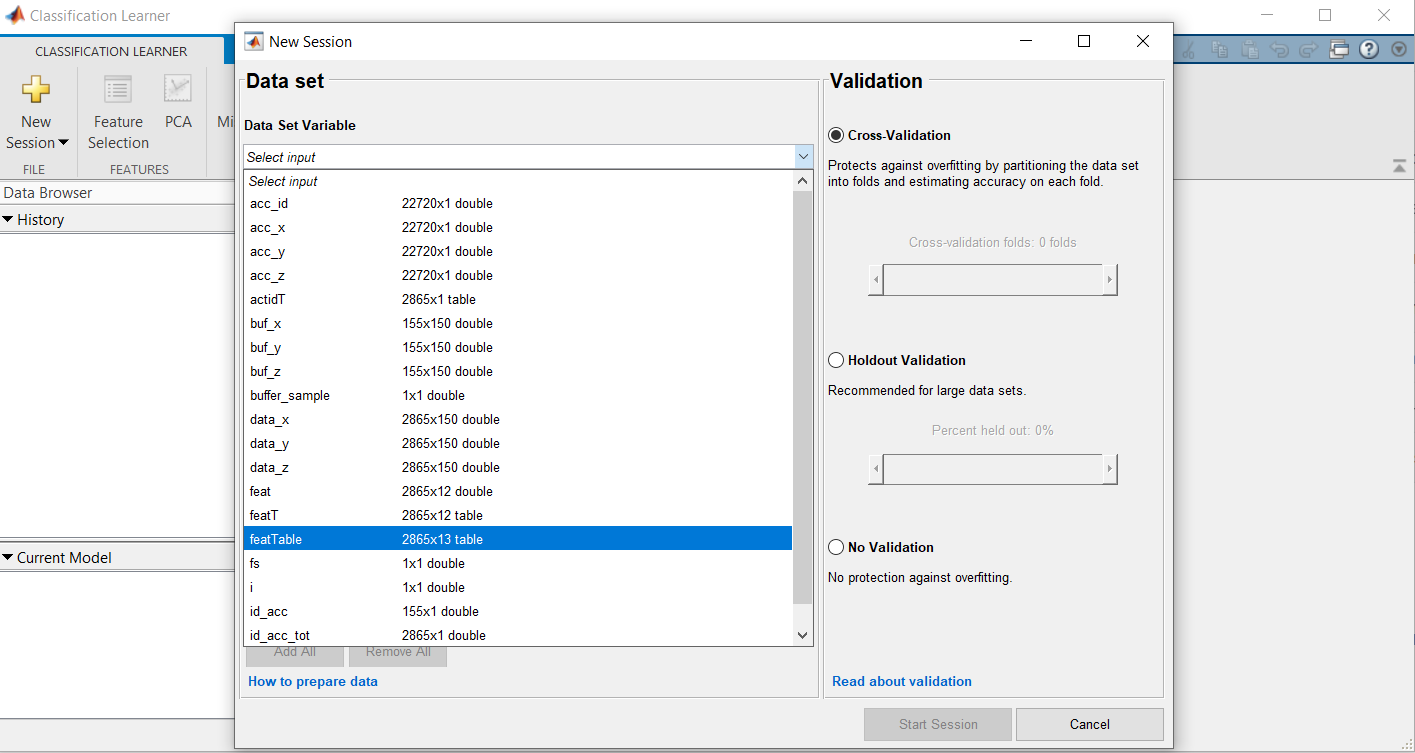

- Scegliere il modello

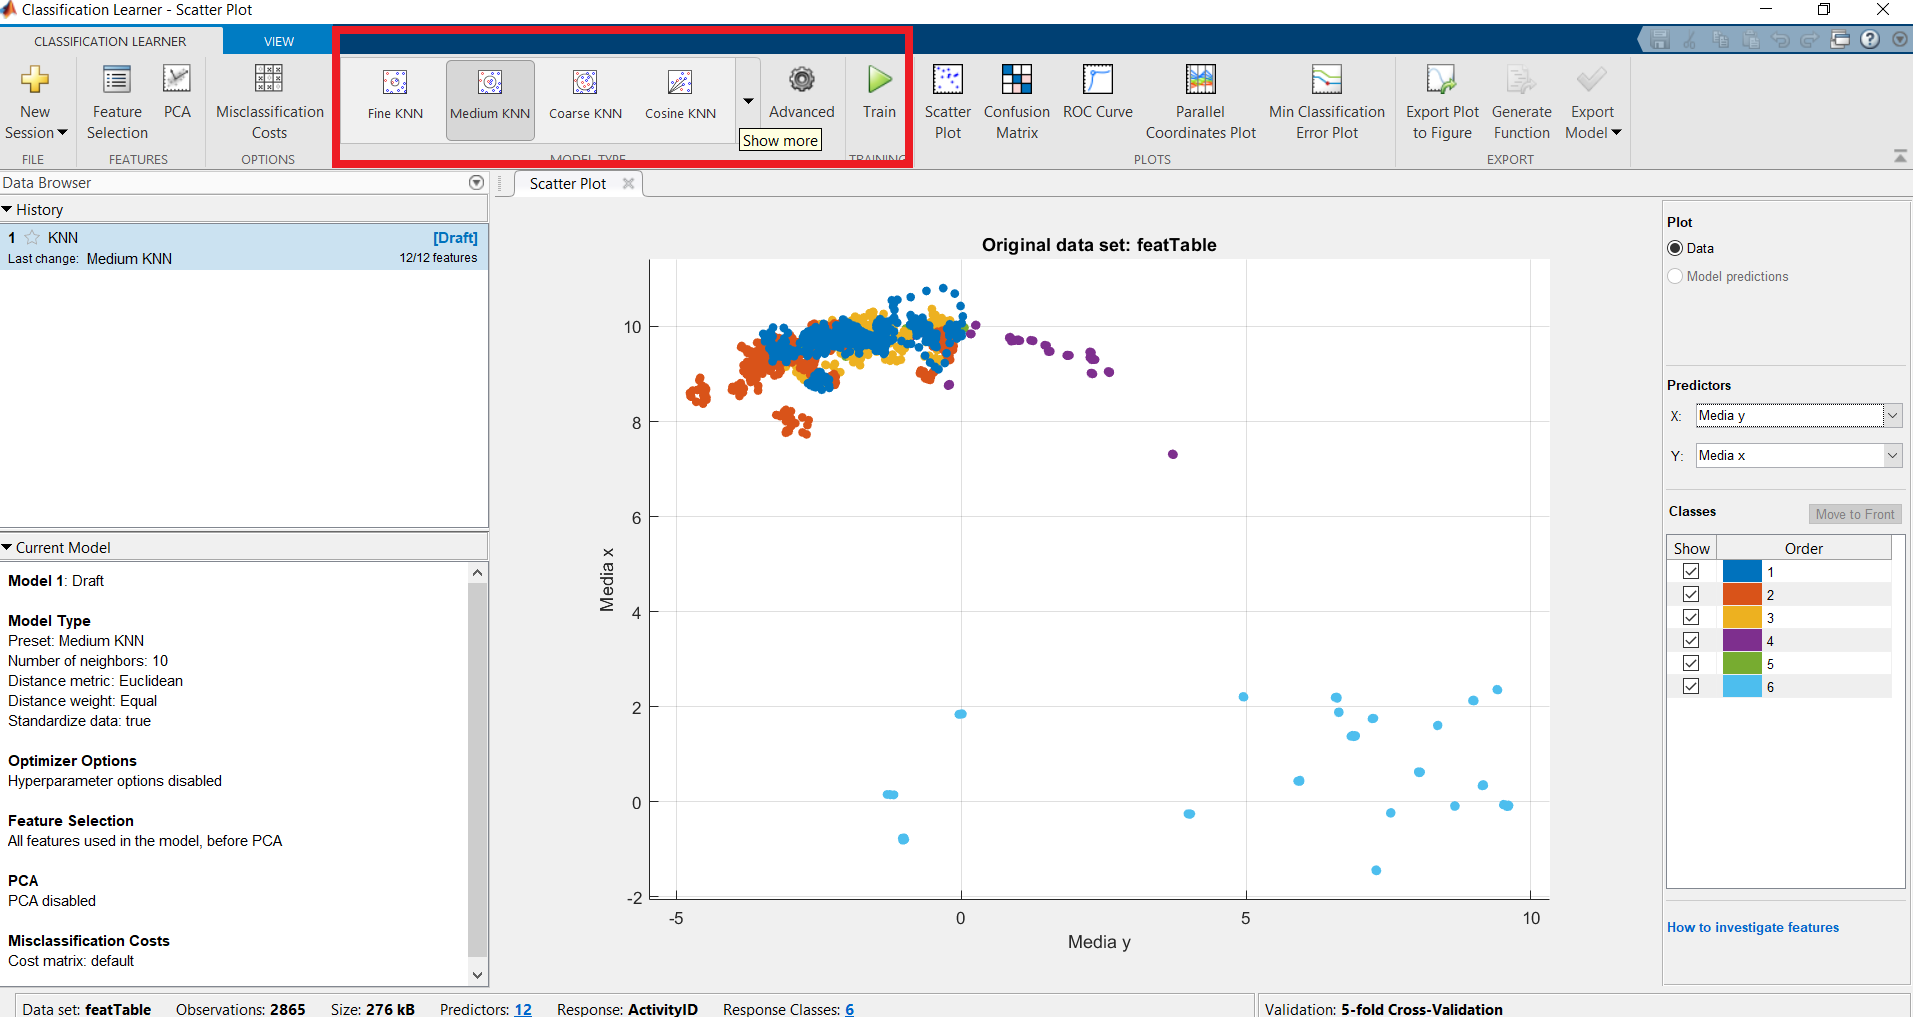

- Scegliere le features utilizzate per la previsione

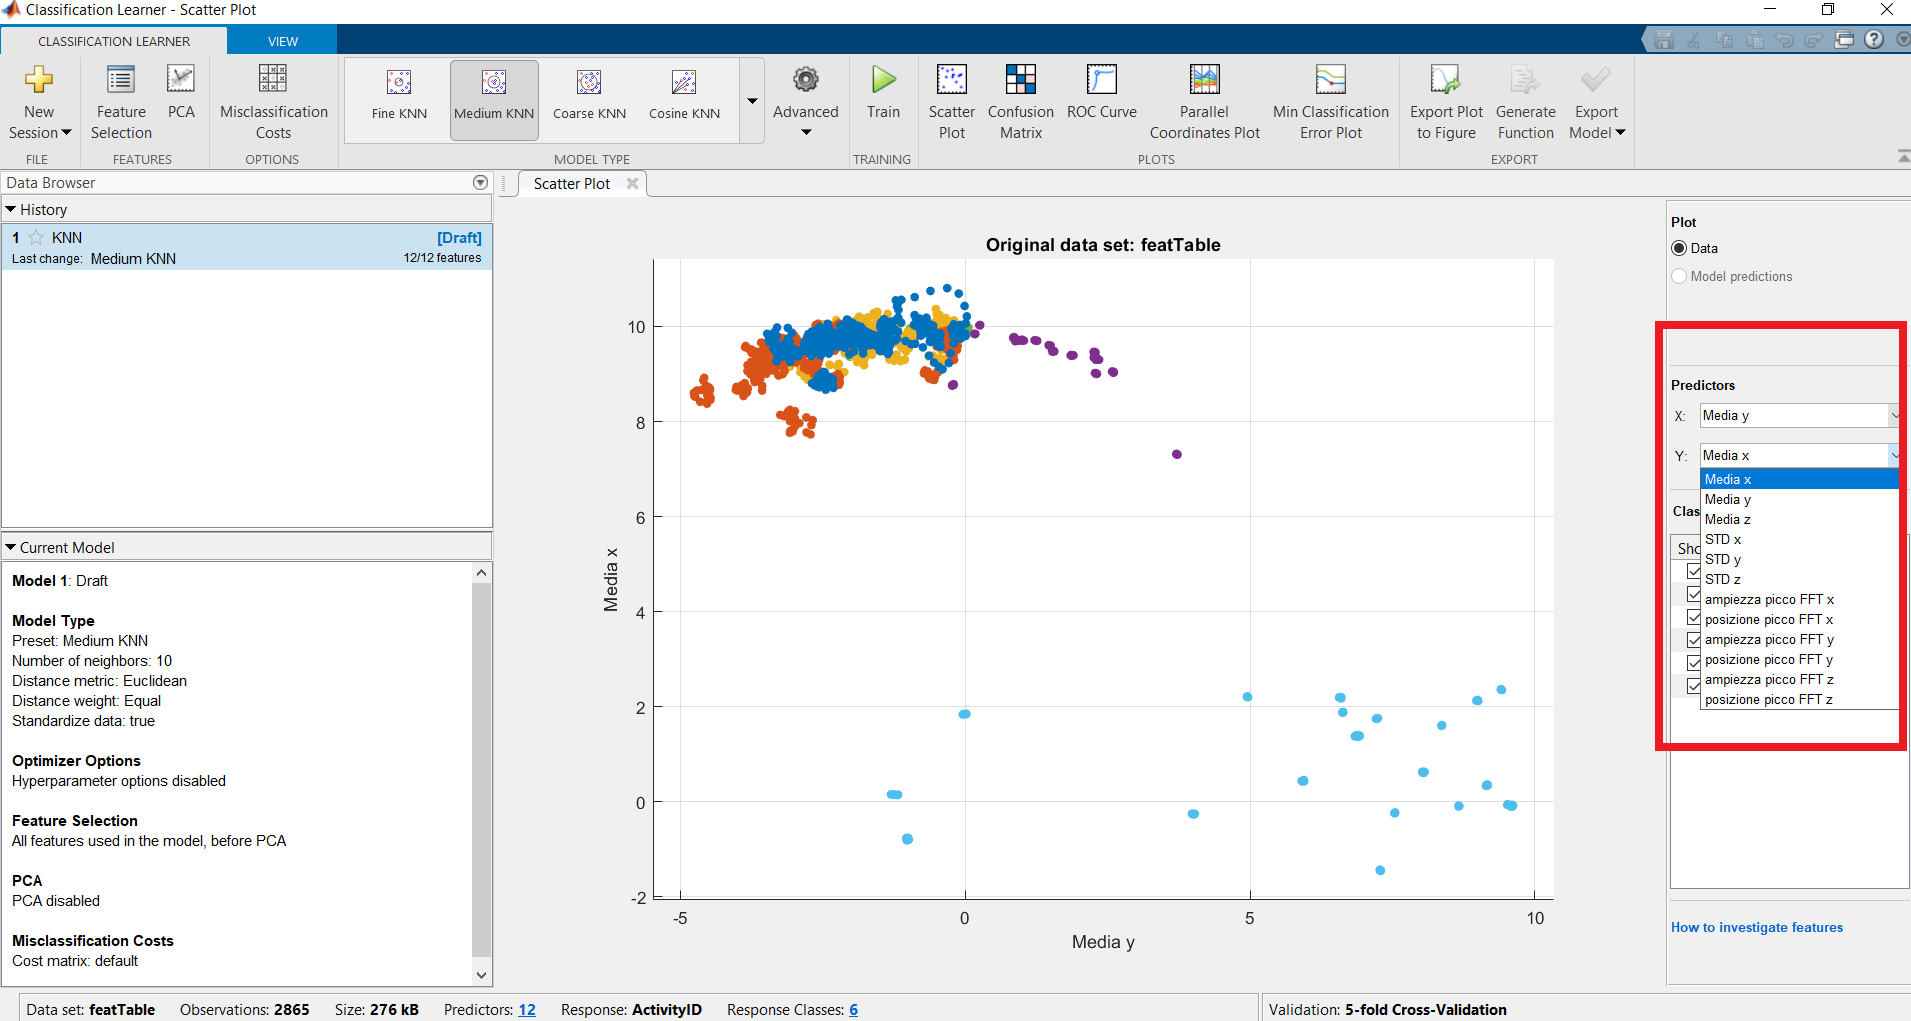

- Esportare il modello

% Classificazione
classificationLearner
% save('modello.mat', 'trainedModel')

#### *Task n°7 : Previsione*

In questo step si richiede di:

**1.    Suddividere il set di dati in due campioni:**

- 80% dei dati (scelti casualmente): TRAINING

- 20% dei dati: TEST

*Consiglio: generare una sequenza di numeri random non ripetuti tramite la funzione "randperm" per ottenere gli indici della specifica riga*

**2.    Realizzare il modello per la previsione delle 6 attività **(utilizzare i dati di training) 

**3.    Testare il modello **(utilizzare i dati di test)

Per effettuare la previsione sui dati di test è possibile seguire due procedimenti:

- Tramite la funzione *predict* (https://it.mathworks.com/help/stats/compactclassificationtree.predict.html)

- Tramite il modello creato utilizzando la funzione interna alla struttura "`predictFcn`" (https://it.mathworks.com/help/stats/export-classification-model-for-use-with-new-data.html)

**4.    Visualizzare la confusion matrix **

Utilizzare il comando MatLab "confusionchart" (https://it.mathworks.com/help/stats/confusionchart.html)